# Getting Started with Volume Labeling Widgets - MATLAB App Building Components

## Description

Volume Labeling Widgets enable advanced GUI programmers to efficiently develop advanced MATLAB apps to implement common medical image processing workflows. The toolbox provides specialized components that implement the building blocks for visualizing and labeling image stacks and 3D isosurfaces resulting from image segmentation.

## Features

Widgets provided in this toolbox include:

- Image Stack / Volume Visualization and Annotation Labeling

- Isosurface Visualization and Annotation Labeling

- Slice Plane (X/Y/Z) visualization

Additionally included are sample apps for:

- Interactively labeling points, lines, polygons, and masks on an image stack volume

- Interactively labeling points, lines, polygons, and planes on a 3D isosurface

## System Requirements

- MATLAB R2020b or later is required. 

- Widgets created from this toolbox must be placed into a uifigure.

## Examples

This toolbox does not have full documentation but is demonstrated by examples. To view the example live scripts, please browse to the toolbox installed directory under the folder "demo".  You can change MATLAB's current directory to that folder by [clicking here](matlab:cd(fileparts(which('demoVolumeViewer.mlx')))).

### Visualizing a Volume by Slice

To start, we need a UI figure. Return the figure handle as `f` so we can place the widget. To position the component nicely, we will also create a uigridlayout object with a single cell.

f = uifigure;
g = uigridlayout(f, [1 1]);

Now we can add a `VolumeViewer` widget to our figure:

viewer = wt.VolumeViewer(g);

To add some data, the imagery needs to be placed inside a `VolumeModel` object. This `VolumeModel` object manages the image data and related metadata for visualization.

In this example, we will create a new `VolumeModel` directly from a folder of DICOM images.

dicomFolder = fullfile(matlabroot,"toolbox","images","imdata","dog");
volModel = wt.model.VolumeModel.fromDicomFile(dicomFolder);

*Note: In this example dataset, the Z-slices of the imagery are not uniformly spaced. You will see a warning but can ignore that for the purposes of this example.*

Finally, we can provide the `VolumeModel` to the VolumeViewer widget for it to be displayed.  

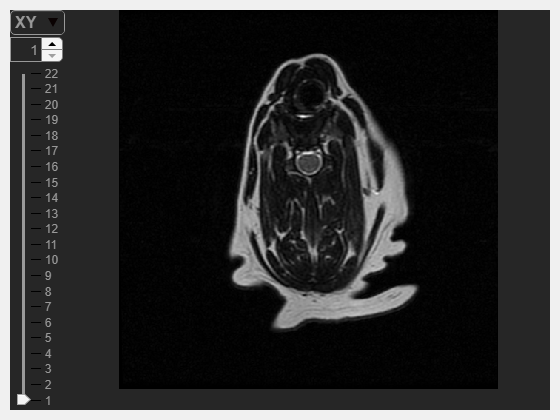

viewer.VolumeModel = volModel;

The DICOM file contains information about the world coordinates. To adjust those, you can edit these properties:

- `WorldExtent`: The coordinate extents of the entire volume from the outermost edges of the first and last pixels in each dimension.

- `WorldExtentPixelCenters`: The coordinate extents of the entire volume from the centers of the first and last pixels in each dimension. (The end pixels partially extend outside the specified range.)

If you set one of these properties, the other will automatically update. It is assumed the pixels are uniformly spaced (`PixelExtent` property) in each individual dimension. This example shows how you might set the `WorldExtent` property:

## Visualizing Slice Planes

Visualizing slice planes is very similar to visualizing a volume by slice, except you see one slice in each of the 3 dimensions.

First, we need a UI figure and grid:

f = uifigure;
g = uigridlayout(f, [1 1]);

Now create the widget and assign data:

viewer2 = wt.SlicePlaneViewer(g);
viewer2.VolumeModel = volModel;

Now, choose the slice position in 3 dimensions:

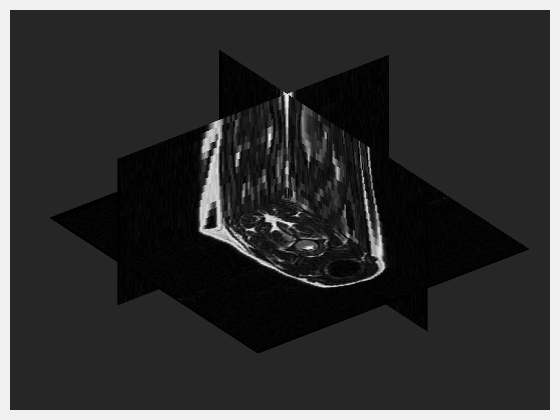

viewer2.Slice = [345 320 7];

This is most useful when building an app where you may have multiple views side-by-side (XY, YZ, XZ planes) and need to be able to see where you are in the volume.

## Visualizing an Isosurface

You may also visualize an Isosurface using `IsosurfaceViewer`. First you need to load in a 3D matrix of data:

s = load('mri.mat');
data = squeeze(s.D);
size(data)

ans =    128   128    27


Then, create an isosurface from the data:

isovalue = 40;
[faces, vertices] = isosurface(data, isovalue);
voxel_size  = [1 1 3];
vertices    = vertices .* voxel_size;
vertexNormals = isonormals(data,vertices);

Now place it into an IsosurfaceModel:

isoModel = wt.model.IsosurfaceModel(...
    'Faces',faces,...
    'Vertices',vertices,...
    'VertexNormals',vertexNormals);

Now we can create the viewer:

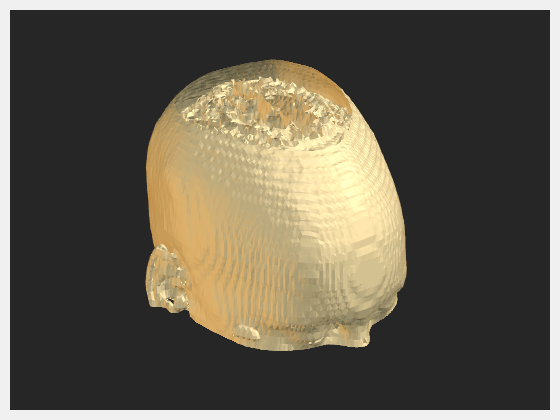

f = uifigure;
g = uigridlayout(f, [1 1]);
viewer3 = wt.IsosurfaceViewer(g);
viewer3.IsosurfaceModel = isoModel;

## Labeling / Annotating a Volume or Isosurface

You may also add label annotations to a volume or isosurface using `VolumeLabeler, VolumeLabelerQuadView, `and `IsosurfaceLabeler` widgets.

For example, let's use the`VolumeLabeler`  widget.

f = uifigure;
g = uigridlayout(f, [1 1]);
viewer4 = wt.VolumeLabeler(g);
viewer4.VolumeModel = volModel;

### Adding Annotations Programmatically

If you have existing data, you can add annotations programmatically:

#### Mask Annotation

You may display a mask on the annotated volume. *This is not applicable to isosurfaces. *For example let's start with a mask that covers pixels over a specified intensity:

intensity = 150;
mask1 = wt.model.MaskAnnotation.fromVolumeModel(volModel,...
    'Mask',volModel.ImageData > intensity,...
    'Color',[0 0 1],...
    'Alpha',0.5);
viewer4.addAnnotation(mask1);

#### Point-based Annotations

There are several similar types of annotation labels applicable to 2D slices of an image volume and to isosurfaces.  They are defined by a set of points:

- `PointsAnnotation` - just a set of points

- `LineAnnotation` - a set of connected points

- `PolygonAnnotation` - a closed shape of connected points

- `PlaneAnnotation` - a plane defined by 3 or more points (more relevant for isosurface)

Here is an example:

points = [
   19.1715  -11.3494  -30.0261
   33.8901   12.6364  -30.0261
   54.0600   -3.7176  -30.0261
   ];
points1 = wt.model.PointsAnnotation('Color',[1 0 0],'Points',points);
viewer4.addAnnotation(points1);

### Changing the Selected Annotation

Note that this annotation is in a different Z-slice within the XY plane, so it appears dimmed in the view. It will appear brighter if you do any of these things:

- Scroll to that slice

- Programmatically change slice

- Click on the annotation points to select it

- Programmatically select it

Let's try programmatically selecting it:

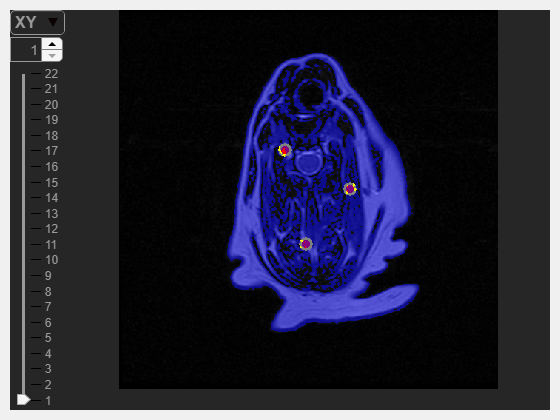

viewer4.selectAnnotation(points1);

### Deleting an Annotation

Annotations may be hidden or removed from the view. To hide an annotation, toggle its visiblity:

You may request a list of annotation objects from the viewer:

allAnnotations = viewer4.AnnotationModel

allAnnotations =   1×2 Heterogeneous BaseAnnotationModel with common properties:

           Name       Color       Alpha    IsVisible    IsSelected    IsBeingEdited       Tag          UserData      ShowObject    SliceRangeFilter    HasLine                Parent                             Type             
           ____    ___________    _____    _________    __________    _____________    __________    ____________    __________    ________________    _______    ____________________________

You may tell the viewer to remove an annotation:

If you forcibly delete the annotation object, it will also be removed:

### Adding Annotations Interactively

You can interactively add these annotations as well. To start:

Add points by clicking on the image. Use the scrollbar or mouse wheel to change slices while editing. If you need to zoom / pan / rotate, you can enter those modes from the toolbar but turn them off again to continue adding points.

You can programmatically end the interactive edits using:

#### Mouse Interactions

While editing a points-based annotation types, the mouse buttons behave this way:

- Left mouse button - add point

- Left button drag - move point

- Right mouse button - delete point

- Double-click left button - finish editing

While editing a mask annotation types, the mouse buttons behave this way:

- Left mouse button click or drag - paint mask

- Right mouse button click or drag - erase mask

- Double-click left button - finish editing

## Building an App Using Volume Labeling Widgets

If you want to build an app using the volume labeling widgets, you may need to know when the user has made a change. The best way to do this is to listen to changes in the model object(s). 

### Listening to Model Changes

You can create a listener to trigger a callback function or method to execute upon changes in the VolumeModel, or to any type of annotation model.

myListener = event.listener(mask1,'PropertyChanged',@(src,evt)disp(evt) );

Now make a change and see the event data `evt`, a property change event, is sent to the `disp` command:

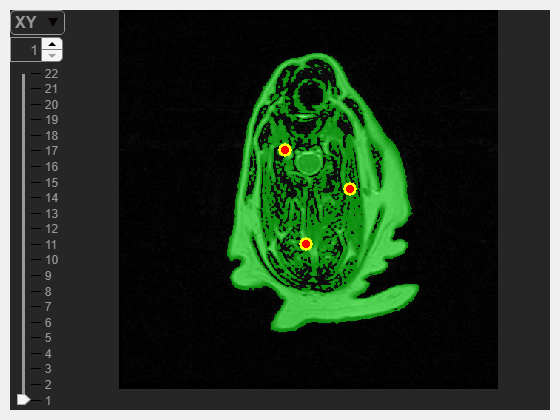

  PropertyChangedData with properties:

            Value: [0 1 0]
    PreviousValue: []
         Property: 'Color'
           Source: [1×1 wt.model.MaskAnnotation]
        EventName: 'PropertyChanged'



mask1.Color = [0 1 0];

mask1.IsVisible = true;

### Special Note: Using Function Handles

Graphics callbacks always provide two input arguments that may be used in your callback function. The first (`src`) is always the object that was interacted upon, and the second (`evt`) is always the event data about the interaction. 

To create the function handle (right of the `=` above), you always need to define the two default arguments `@(src, evt)` before the callback function name. After the function name, you may choose whether or not these inputs get passed in to the function. 

You may pass additional arguments into the callback as well. Those additional inputs must be defined in the current workspace when you create the function handle.

If your callback is calling the method of an object, you need to use the object notation that looks like any of these:

© 2019-2021 The MathWorks, Inc.